A=[-6 0 ; 1 0];
B=[1 ; 0];
C=[0 9];
D=0;

[fi,gama,C_1,D_1]=c2dm(A,B,C,D,0.1,'zoh');
[numz,denz]=ss2tf(fi,gama,C_1,D_1);
[nz,dz]=feedback(numz, denz,1,1);

[fi_1,gama_1,C_2,D_2]=tf2ss(nz,dz)

fi_1 =     1.5116   -0.5793
    1.0000         0


gama_1 =      1
     0


C_2 =     0.0372    0.0305


D_2 = 0

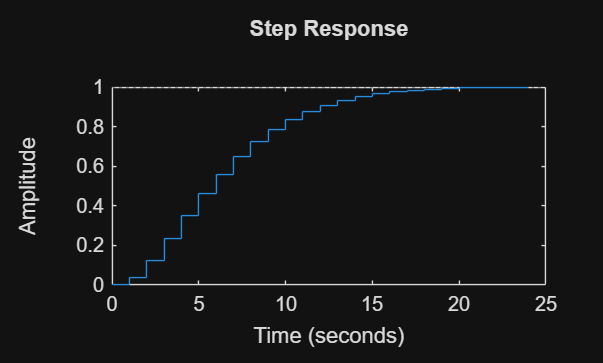

dstep(fi_1,gama_1,C_2,D_2)


ctb = det(ctrb(fi_1,gama_1))

ctb = 1

obs = det(obsv(fi_1,C_2))

obs = -0.0034